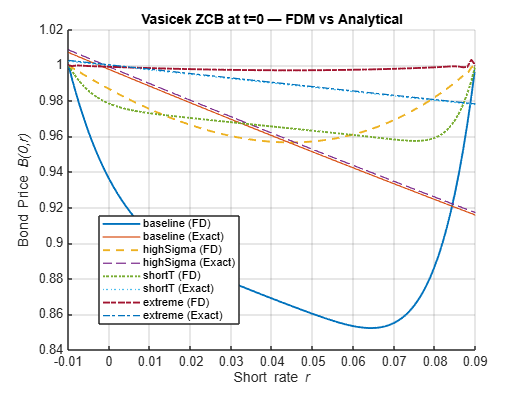

%% Vasicek ZCB via Crank–Nicolson Finite Differences
% Multiple Test Scenarios + Error Tables + Plots (matching FEM format)

clear; clf;

%% 1) Common parameters & spatial mesh
a     = 0.1;      % mean‑reversion speed
b     = 0.05;     % long‑term mean
r_min = -0.01;
r_max =  0.09;
num_r = 100;                              % spatial subdivisions
r     = linspace(r_min, r_max, num_r)';   % column vector of nodes
dr    = r(2) - r(1);

%% 2) Define test scenarios
testCases = struct(...
  'name',  {'baseline','highSigma','shortT','extreme'},...
  'sigma', {0.02,       0.10,       0.02,     0.40   },...
  'T',     {1.00,       1.00,       0.25,     0.25   }...
);
nCases = numel(testCases);

% Preallocate storage for errors and solutions
L2err     = zeros(nCases,1);
H1err     = zeros(nCases,1);
Bnum_mat  = zeros(num_r, nCases);
Bex_mat   = zeros(num_r, nCases);

%% 3) Loop over each scenario, solve by FD + CN, compute errors
for k = 1:nCases
    sigma_k = testCases(k).sigma;
    T_k     = testCases(k).T;

    % time mesh in tau = T - t
    num_tau = 101;
    tau     = linspace(0, T_k, num_tau)';
    dt      = tau(2) - tau(1);

    % PDE coefficients
    kappa     = 0.5 * sigma_k^2;
    alpha_arr = a * (b - r);    % vector of drift terms
    beta_arr  = r + a;          % reaction

    % initial condition: B(τ=0)=1
    u = ones(num_r,1);

    % build FD operator on interior nodes (2..num_r-1)
    M_int = num_r - 2;
    A_int = kappa/dr^2 - alpha_arr(2:end-1)/(2*dr);
    B_int = -2*kappa/dr^2 - beta_arr(2:end-1);
    C_int = kappa/dr^2 + alpha_arr(2:end-1)/(2*dr);
    L_int = diag(B_int) ...
          + diag(C_int(1:end-1),1) ...
          + diag(A_int(2:end),-1);
    I_int = eye(M_int);
    M1    = I_int - 0.5*dt * L_int;
    M2    = I_int + 0.5*dt * L_int;

    % analytic bond‐price helpers
    Btau = @(tt) (1 - exp(-a*(T_k - tt))) / a;
    Atau = @(tt) (Btau(tt) - (T_k - tt))*(b - sigma_k^2/(2*a^2)) ...
                 - (sigma_k^2 * Btau(tt).^2)/(4*a);

    % Crank–Nicolson time‐stepping
    for n = 1:num_tau-1
        t_n   = tau(n);
        t_np1 = tau(n+1);
        % Dirichlet BCs at old and new times
        gL_n   = exp( Atau(t_n)   - Btau(t_n)  * r_min );
        gR_n   = exp( Atau(t_n)   - Btau(t_n)  * r_max );
        gL_np1 = exp( Atau(t_np1) - Btau(t_np1)* r_min );
        gR_np1 = exp( Atau(t_np1) - Btau(t_np1)* r_max );

        % interior solution
        U_n = u(2:end-1);

        % coupling from BCs
        bc_old = zeros(M_int,1);
        bc_new = zeros(M_int,1);
        bc_old(1)     = 0.5*dt * A_int(1)       * gL_n;
        bc_new(1)     = 0.5*dt * A_int(1)       * gL_np1;
        bc_old(end)   = 0.5*dt * C_int(end)     * gR_n;
        bc_new(end)   = 0.5*dt * C_int(end)     * gR_np1;

        % RHS and solve
        rhs = M2*U_n + bc_old + bc_new;
        U_np1 = M1 \ rhs;

        % reassemble full solution vector
        u = [gL_np1; U_np1; gR_np1];
    end

    % store numeric and exact at t=0
    B_num0       = u;
    B_ex0        = exp( Atau(0) - Btau(0).*r );
    Bnum_mat(:,k)= B_num0;
    Bex_mat(:,k) = B_ex0;

    % compute errors
    L2err(k) = sqrt( trapz(r, (B_num0 - B_ex0).^2 ) );
    d_num    = gradient(B_num0, dr);
    d_ex     = gradient(B_ex0,  dr);
    H1err(k) = sqrt( trapz(r, (d_num - d_ex).^2 ) );
end

%% 4) Plot numerical vs analytical curves for all scenarios
figure; hold on;
lineStyles = {'-','--',':','-.'};
for k = 1:nCases
    plot(r, Bnum_mat(:,k), lineStyles{k}, 'LineWidth',1.5,   ...
         'DisplayName',[testCases(k).name ' (FD)']);
    plot(r, Bex_mat(:,k),  lineStyles{k}, 'LineWidth',1.0,   ...
         'DisplayName',[testCases(k).name ' (Exact)']);
end
xlabel('Short rate \itr'); ylabel('Bond Price \itB(0,r)');
title('Vasicek ZCB at t=0 — FDM vs Analytical');
legend('Location','best'); grid on;

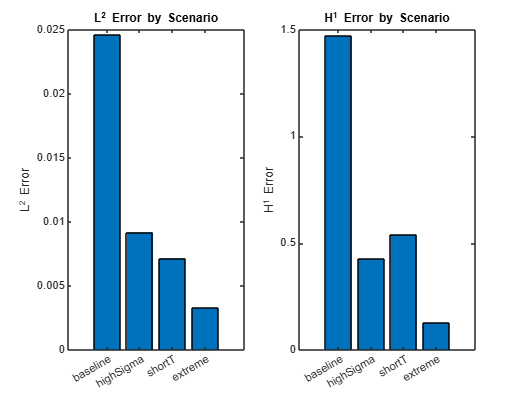


%% 5) Bar charts of errors by scenario
figure;
subplot(1,2,1);
bar(L2err);
set(gca,'XTick',1:nCases,'XTickLabel',{testCases.name});
ylabel('L^2 Error'); title('L^2 Error by Scenario');
subplot(1,2,2);
bar(H1err);
set(gca,'XTick',1:nCases,'XTickLabel',{testCases.name});
ylabel('H^1 Error'); title('H^1 Error by Scenario');


%% 6) Display error table
Scenario = {testCases.name}';
Sigma    = [testCases.sigma]';
Tmat     = [testCases.T]';
Results  = table(Scenario, Sigma, Tmat, L2err, H1err, ...
                   'VariableNames',{'Scenario','Sigma','T','L2Error','H1Error'});
disp(Results);

      Scenario       Sigma     T       L2Error     H1Error
    _____________    _____    ____    _________    _______

    {'baseline' }    0.02        1     0.024614     1.4717
    {'highSigma'}     0.1        1    0.0091876    0.42572
    {'shortT'   }    0.02     0.25    0.0071585     0.5396
    {'extreme'  }     0.4     0.25    0.0032971    0.12575




%% 7) Print test‐case definitions
fprintf('\nTest Case Definitions:\n');


Test Case Definitions:


for k = 1:nCases
    fprintf('  %-10s: sigma=%.2f, T=%.2f\n', ...
            testCases(k).name, testCases(k).sigma, testCases(k).T);
end

  baseline  : sigma=0.02, T=1.00
  highSigma : sigma=0.10, T=1.00
  shortT    : sigma=0.02, T=0.25
  extreme   : sigma=0.40, T=0.25
